# Feature selection and extraction

We have the total data  saved in "**data10_Real_clean**" set. Firstly, we obtain a new feature : **MIS (wind-waves misalignment)**

## 1 New feature: Misalignment

data10_Real_clean = calculateMis(data10_Real_clean)

data10_Real_clean = 69282x16 table
     YY     MM    DD    hh    mm    WDIR    WSPD    GST    WVHT     DPD     APD     MWD     PRES     ATMP    WTMP    MIS
    ____    __    __    __    __    ____    ____    ___    ____    _____    ____    ___    ______    ____    ____    ___

    2010    2     16    23    50    319       7     8.5    2.45    13.79    8.04    282    1014.5    14.5    13.8     37
    2010    2     17     0    50    320     6.6     7.8  

## 2 Inital data sets

data2018 = data10_Real_clean(data10_Real_clean.YY == 2018,:);
data2019 = data10_Real_clean(data10_Real_clean.YY == 2019,:);
dataRealTime = data10_Real_clean(data10_Real_clean.YY == 2020,:);
data10_18 = data10_Real_clean(data10_Real_clean.YY ~= 2019 & data10_Real_clean.YY ~= 2020,:);

 Now we are going to study the significance of features respect to the variable we want to predict, by applying the **F-score technique **to data from 2018.

## 3 F-test score - Features significance study

### For Wind speed forecasting

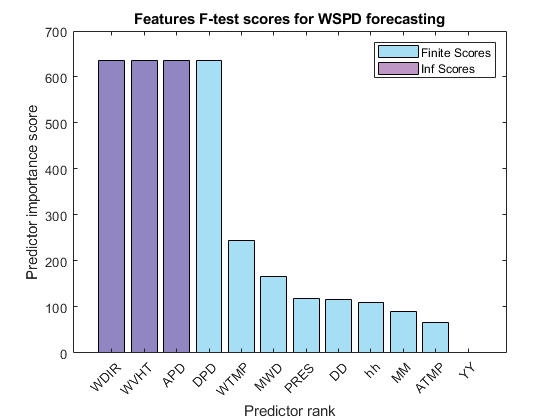

idx =      5     6     8     7    12     9    10     3     4     2    11     1


scores =          0   90.2098  117.2723  109.5398  635.5853  635.5853  635.5853  635.5853  166.5324  117.9960   65.2230  243.8173


b1 =   Bar (Finite Scores) with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.3010 0.7450 0.9330]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12]
        YData: [635.5853 635.5853 635.5853 635.5853 243.8173 166.5324 117.9960 117.2723 109.5398 90.2098 65.2230 0]

  Show all properties


[idx, scores,b1] = fSelection(data2018(:,{'YY','MM','DD','hh','WDIR','WSPD','WVHT','DPD','APD','MWD','PRES','ATMP','WTMP'}),'WSPD')

We observe every feature except YY gives a* F*-test score higher that 1.3, especially WDIR and WVHT (and therefore DPD and APD) are highly significant in relation to Wind speed

### For Waves forecasting

Let's explore features F-test scores  for Significant Wave height (WVHT) forecasting

Let's apply Feature selection method

[idx2, scores2,b2] = fSelection(data2018(:,{'MM','DD','hh','WDIR','WSPD','WVHT','DPD','APD','MWD','PRES','ATMP','WTMP'}),'WVHT')

### For Misalignment forecasting

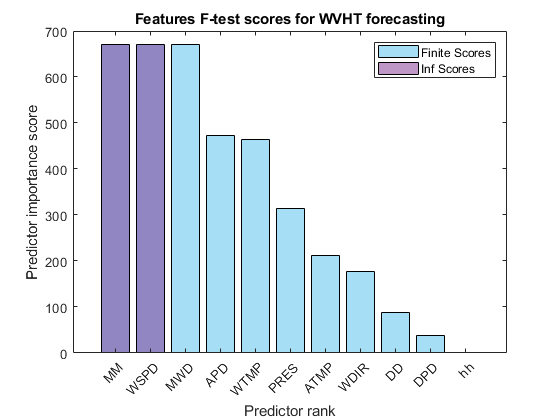

idx2 =      1     5     8     7    11     9    10     4     2     6     3


scores2 =   671.1943   87.0205    0.0556  176.6359  671.1943   38.7265  471.9295  671.1943  314.8759  212.9943  463.2801


b2 =   Bar (Finite Scores) with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.3010 0.7450 0.9330]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11]
        YData: [671.1943 671.1943 671.1943 471.9295 463.2801 314.8759 212.9943 176.6359 87.0205 38.7265 0.0556]

  Show all properties


[idx, scores,b1] = fSelection(data2018(:,{'MM','DD','hh','WSPD','WVHT','DPD','APD','PRES','ATMP','WTMP','MIS'}),'MIS')

## 4 Data combination for time series forecasting

### Wind speed forecasting

To obtain the data sets with data from 1, 2,..., 6 hours before : use the files .m listed above

Data  from 1 hour-before : 1hbefore_WSPD.m

Data from 2 h-before: 2hbefore_WSPD.m

...

Data from 6h-before: 6hbefore_WSPD.m

**For wind speed forecasting with NAR and NARX**

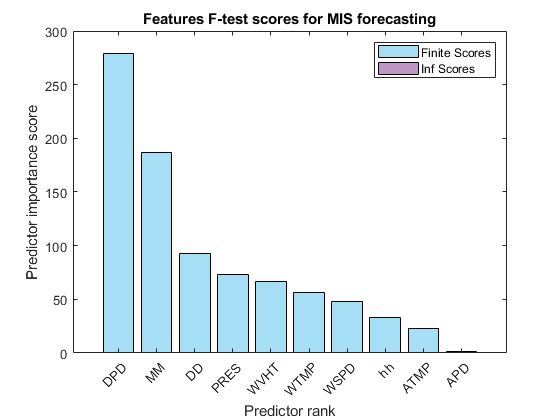

idx =      6     1     2     8     5    10     4     3     9     7


scores =   186.7756   93.1225   32.9219   48.1088   66.4262  279.3149    1.7921   72.7828   22.9956   56.5766


b1 =   Bar (Finite Scores) with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.3010 0.7450 0.9330]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10]
        YData: [279.3149 186.7756 93.1225 72.7828 66.4262 56.5766 48.1088 32.9219 22.9956 1.7921]

  Show all properties


targetsWind2018 = data2018.WSPD;

targetsWind2019 = data2019.WSPD;
targetsWindRealTime = dataRealTime.WSPD;
predictorsWind2018 = table2array(data2018(:,{'WSPD','ATMP','PRES','WDIR'}));
predictorsWind2019 = table2array(data2019(:,{'WSPD','ATMP','PRES','WDIR'}));
predictorsWindRealTime = table2array(dataRealTime(:,{'WSPD','ATMP','PRES','WDIR'}));


### Significant Waves height forecasting

For Significant Waves Height prediction in the frequency domain we select features in the Regression learner toolbox directly from the initial data sets

On the other hand, for Feedforward neural networks we separate predictors and targets:

predictorsWaves2018a = table2array(data2018(:,{'WSPD','MWD','WDIR'}))';
predictorsWaves2018b = table2array(data2018(:,{'WSPD','MWD','WDIR','PRES','WTMP'}))';
targetsWaves2018 = data2018.WVHT;

predictorsWaves2019a = table2array(data2019(:,{'WSPD','MWD','WDIR'}))';
predictorsWaves2019b = table2array(data2019(:,{'WSPD','MWD','WDIR','PRES','WTMP'}))';
targetsWaves2019 = data2019.WVHT;

predictorsWavesRealTimea = table2array(dataRealTime(:,{'WSPD','MWD','WDIR'}))';
predictorsWavesRealTimeb = table2array(dataRealTime(:,{'WSPD','MWD','WDIR','PRES','WTMP'}))';
targetsWavesRealTime = dataRealTime.WVHT;

### **Misalignment Forecasting**

To obtain the data sets with data from 1 hour before we execute 1hoursbefore_MIS.m

Other tries of modeling with more hours before values as predictors have been made giving similar or even poorest results, so this models haven't been include in the memory and thus data sets with more than 1 hour before predictors have not been included in the repository.

**For NAR and NARX training and testing:**

predictorsMis2018a = table2array(data2018(:,{'MIS','WSPD'}));
predictorsMis1018a = table2array(data10_Real_clean(data10_Real_clean.YY ~= 2019 & data10_Real_clean.YY ~= 2020,{'MIS','WSPD'}));
predictorsMis2019a = table2array(data10_Real_clean(data10_Real_clean.YY == 2019,{'MIS','WSPD'}));
predictorsMisRealTimea = table2array(data10_Real_clean(data10_Real_clean.YY == 2020,{'MIS','WSPD'}));

targetMis2018 = table2array(data10_Real_clean(data10_Real_clean.YY == 2018,{'MIS'}));
targetMis1018 = table2array(data10_Real_clean(data10_Real_clean.YY ~= 2019 & data10_Real_clean.YY ~= 2020,{'MIS'}));
targetMis2019 = table2array(data10_Real_clean(data10_Real_clean.YY == 2019,{'MIS'}));
targetMisRealTime = table2array(data10_Real_clean(data10_Real_clean.YY == 2020,{'MIS'}));